lena=imread('Database\Images\Lena.jpg');
lenasize=size(lena)

lenasize =    512   512     3


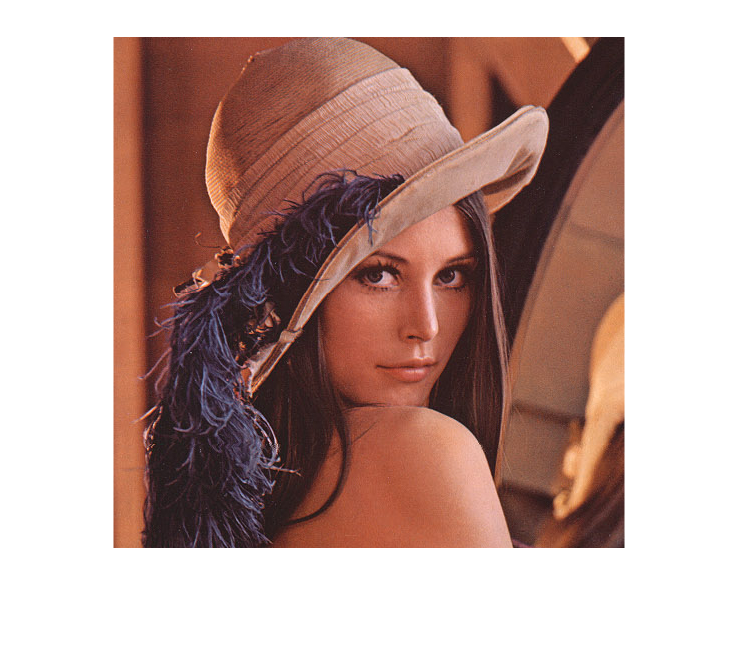

imshow(lena);

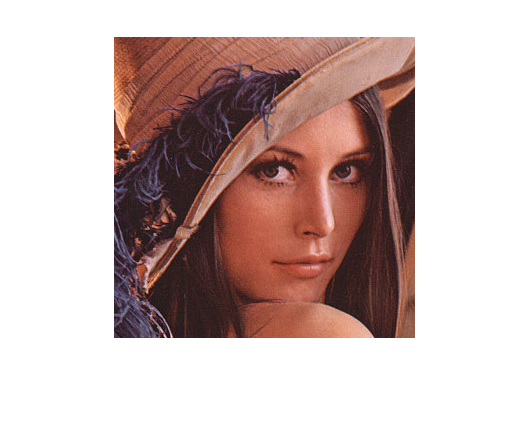

lenacut=lena(106:406,106:406,:);
imshow(lenacut)

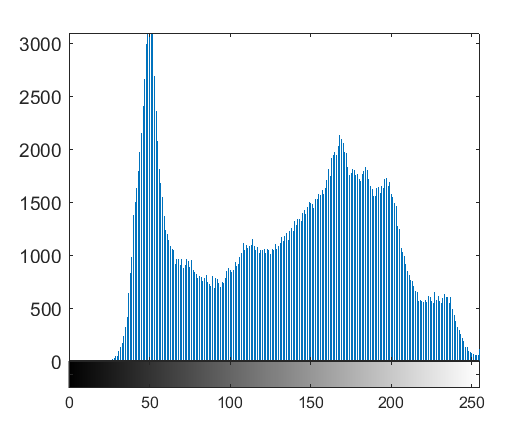

imhist(lena(:,:,1))

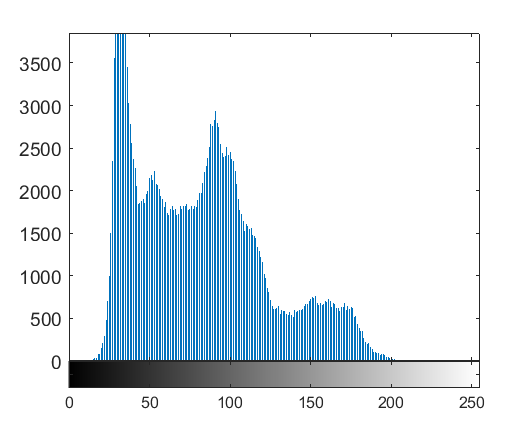

imhist(lena(:,:,2))

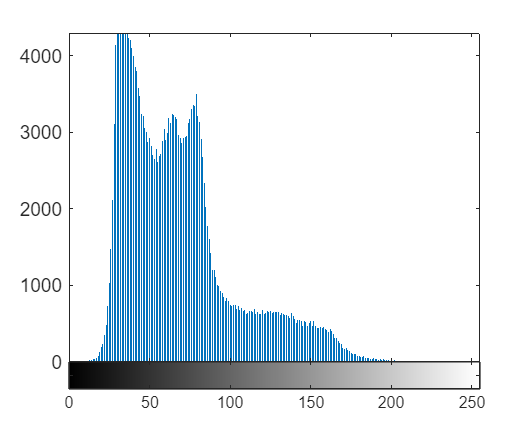

imhist(lena(:,:,3))

random1=uint8(rand(512,512).*255);
random2=uint8((randn(512,512).*31)+127);

max(max(random1))

ans = uint8
255

min(min(random1))

ans = uint8
0

mean(mean(random1))

ans = 127.6391

max(max(random2))

ans = uint8
255

min(min(random2))

ans = uint8
0

mean(mean(random2))

ans = 127.0353

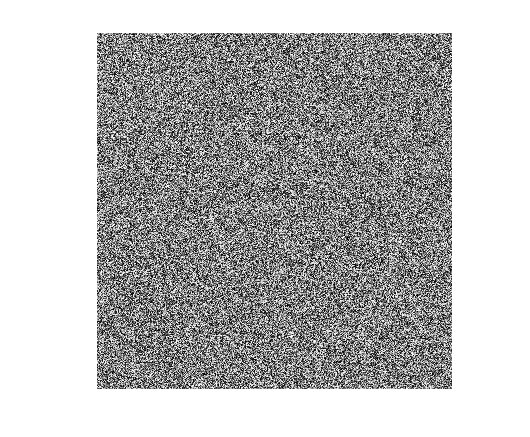

imshow(random1)

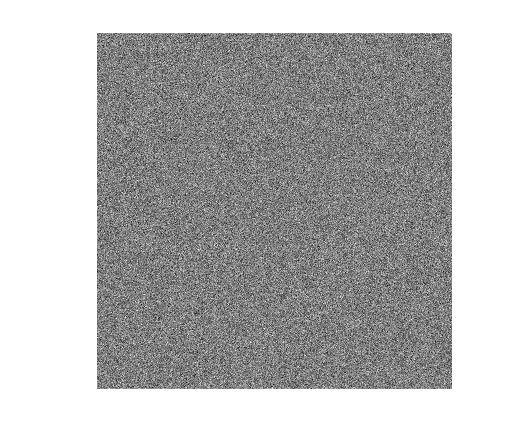

imshow(random2)

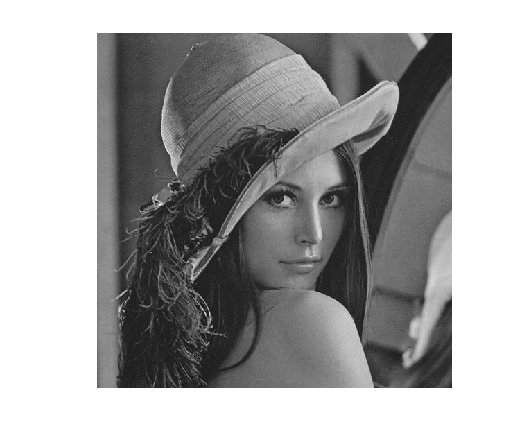

lenagray = rgb2gray(lena);
imshow(lenagray)

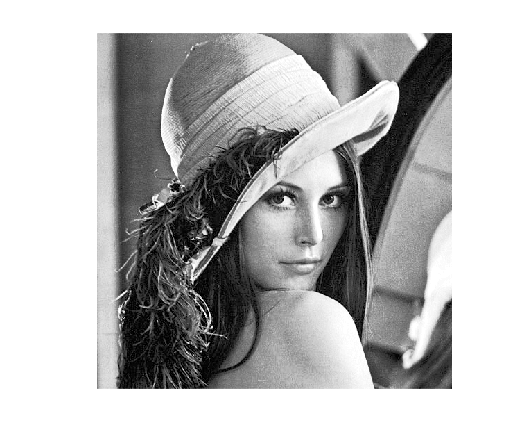


eqlenagrry=histeq(lenagray);
imshow(eqlenagrry)

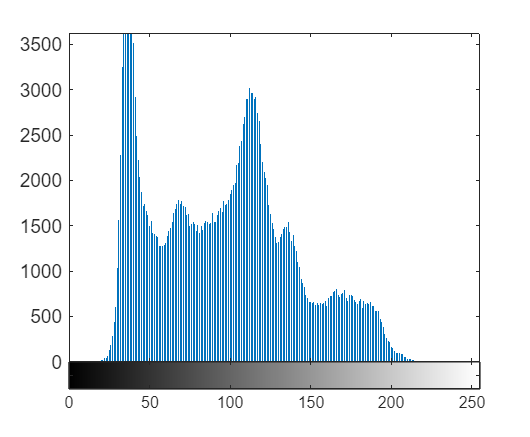

% subplot(2,1,1)
imhist(lenagray)

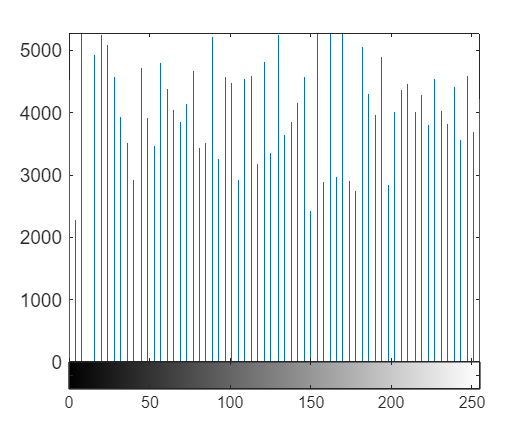

% subplot(2,1,2)
imhist(eqlenagrry)

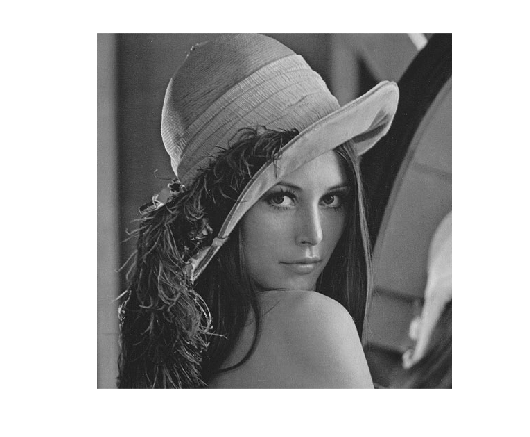

LP2=[1 2 1;2,4,2;1 2 1];
HP1=[-1 -2 -1;0 0 0;1 2 1];
HP2=[-1 0 1;-2 0 2;-1 0 1];
HP3=[0 -1 0;-1 4 -1;0 -1 0];

mask1=(1/9).*[1 1 1; 1 1 1; 1 1 1];
mask2=(1/sum(sum(LP2))).*LP2;


LP1f=uint8(conv2(lenagray,mask1));
LP2f=uint8(conv2(lenagray,mask2));
HP1f=uint8(conv2(lenagray,HP1));
HP2f=uint8(conv2(lenagray,HP2));
HP3f=uint8(conv2(lenagray,HP3));
HP4f=uint8(conv2(lenagray,HP3+[0 0 0;0 1 0;0 0 0]));

imshow(lenagray)


disp((1/9).*[1 1 1; 1 1 1; 1 1 1])

    0.1111    0.1111    0.1111
    0.1111    0.1111    0.1111
    0.1111    0.1111    0.1111



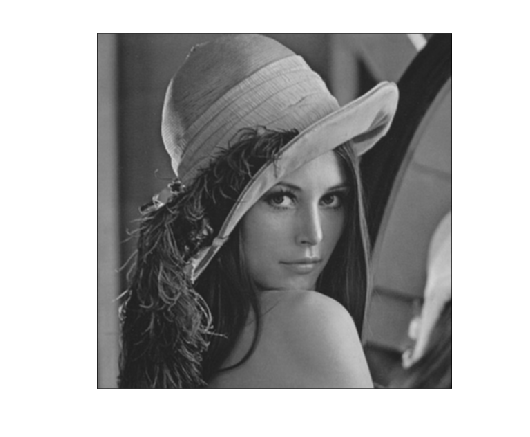

imshow(LP1f)


disp((1/sum(sum(LP2))).*LP2)

    0.0625    0.1250    0.0625
    0.1250    0.2500    0.1250
    0.0625    0.1250    0.0625



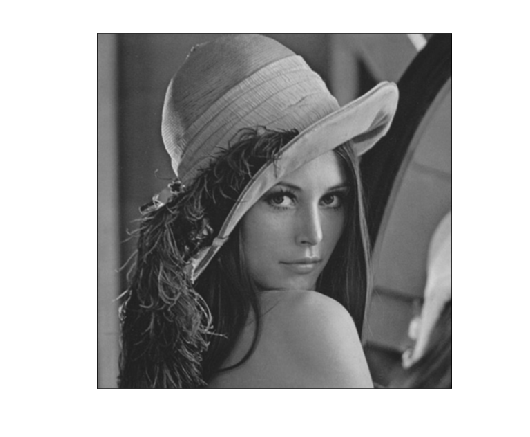

imshow(LP2f)


disp([-1 -2 -1;0 0 0;1 2 1])

    -1    -2    -1
     0     0     0
     1     2     1



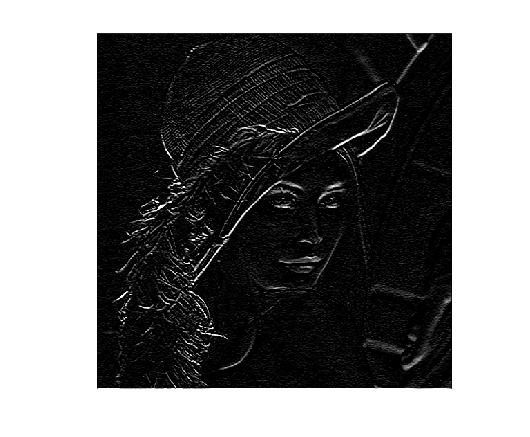

imshow(HP1f)


disp([-1 0 1;-2 0 2;-1 0 1])

    -1     0     1
    -2     0     2
    -1     0     1



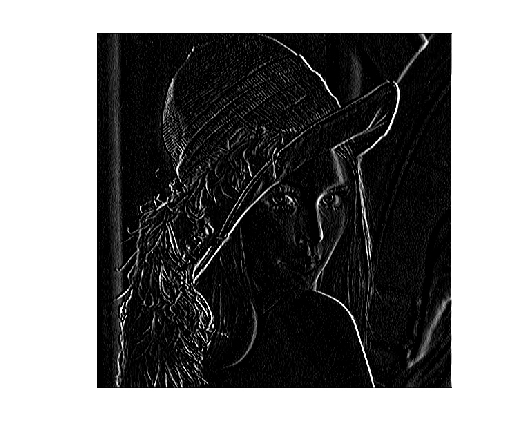

imshow(HP2f)

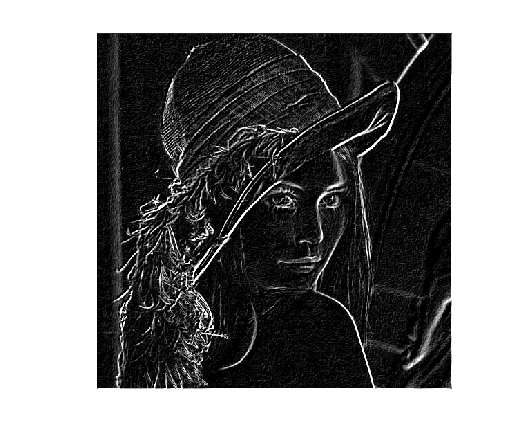


imshow(HP1f+HP2f)


disp([0 -1 0;-1 4 -1;0 -1 0])

     0    -1     0
    -1     4    -1
     0    -1     0



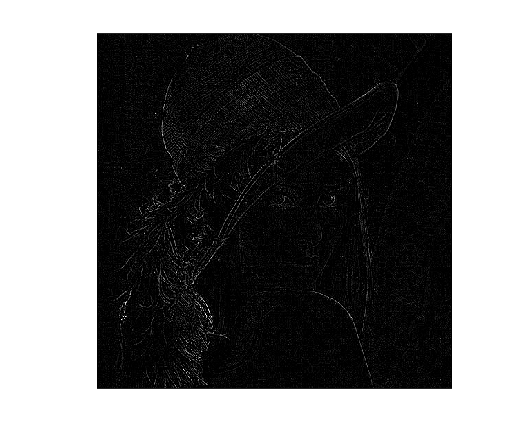

imshow(HP3f)

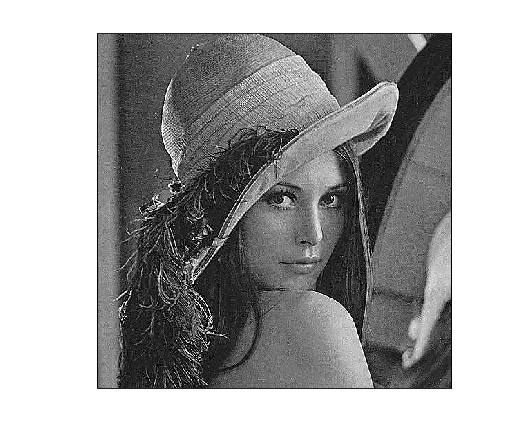


imshow(HP4f)

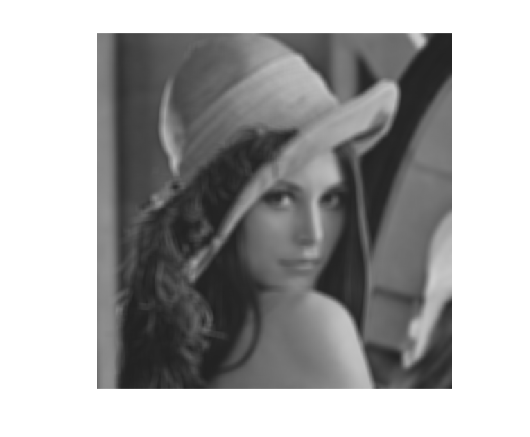

h = fspecial('average', [10 10]);
im_filt = imfilter(lenagray,h,'replicate');
imshow(uint8(im_filt));

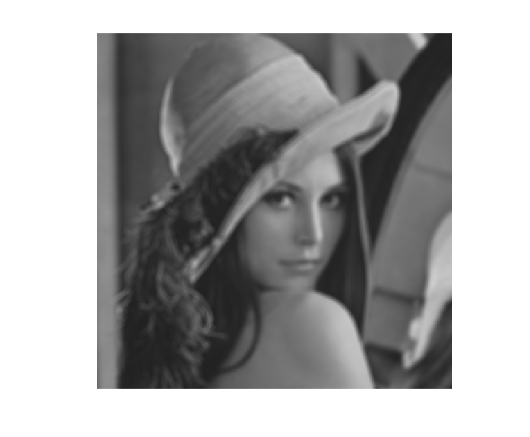

h2 = fspecial('disk', 5);
im_filt2 = imfilter(lenagray,h2,'replicate');
imshow(uint8(im_filt2));

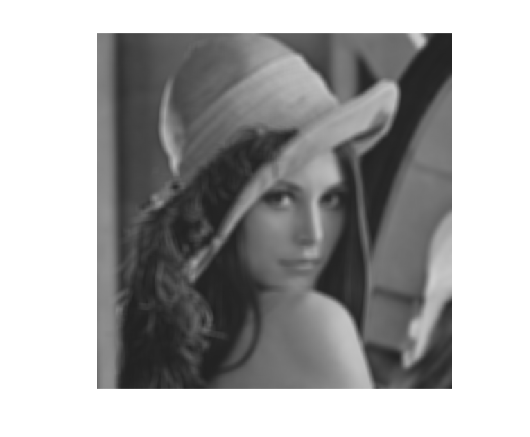

h3 = fspecial('gaussian', [10 10], 10);
im_filt3 = imfilter(lenagray,h3,'replicate');
imshow(uint8(im_filt3));

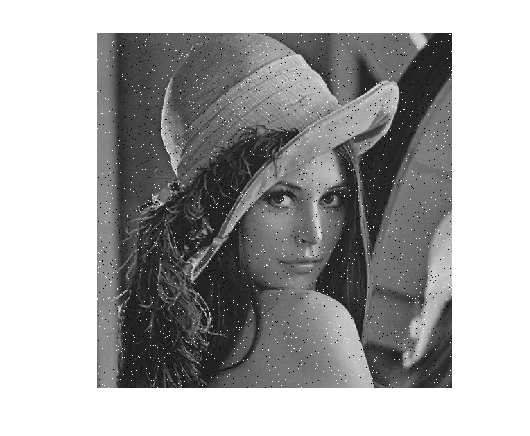

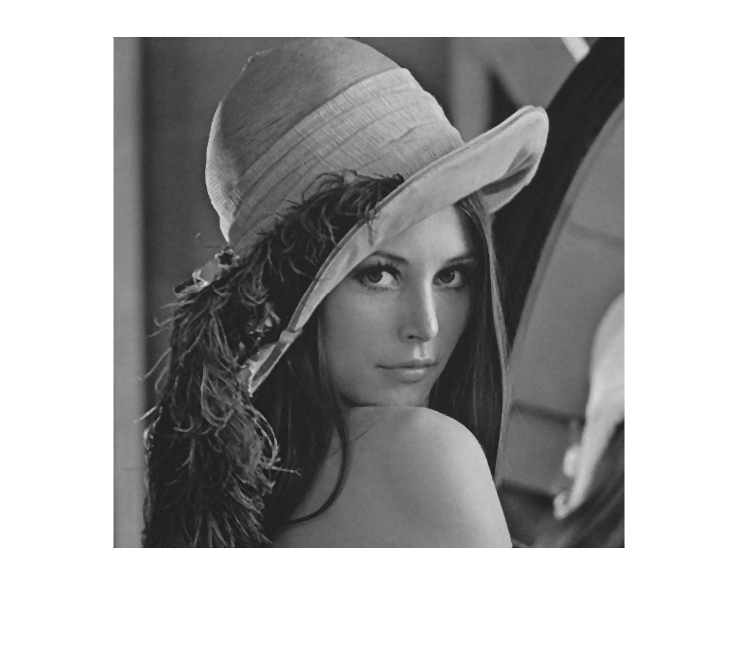

im_noise = imnoise(lenagray,'salt & pepper',0.02);
im_filtered = medfilt2(im_noise);
imshow(im_noise), figure, imshow(im_filtered)

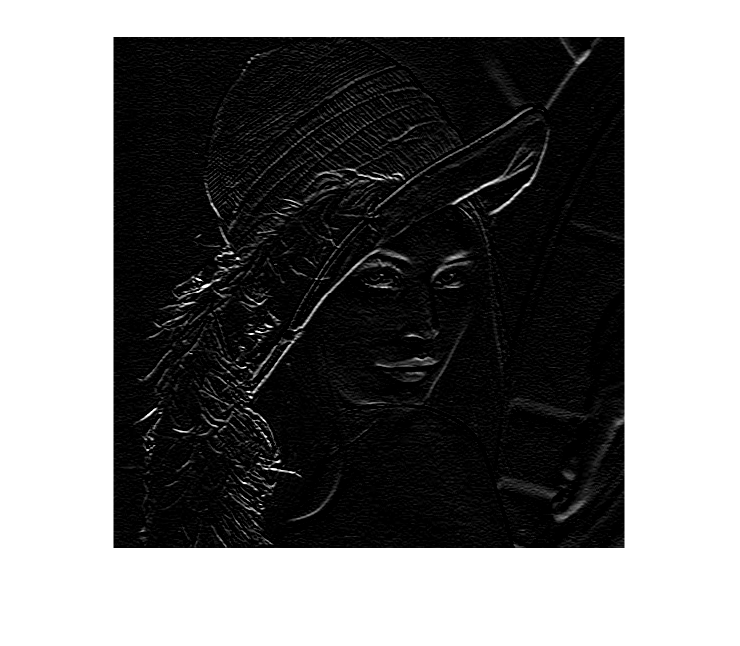

h = fspecial('prewitt');
im_filt = imfilter(lenagray,h,'replicate');
imshow(uint8(im_filt));

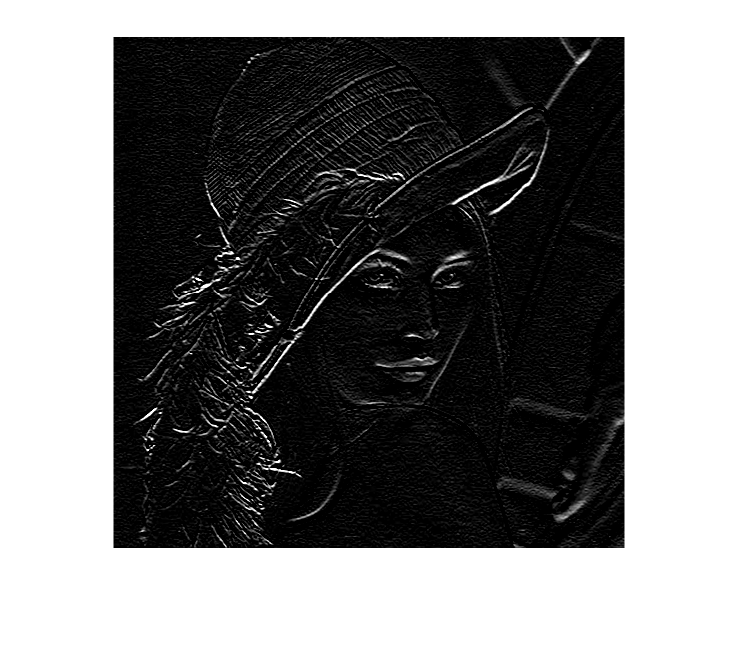

h1 = fspecial('sobel');
im_filt = imfilter(lenagray,h1,'replicate');
imshow(uint8(im_filt));